## Data Loading

DrivFace = load("data/DrivFace/DrivFace.mat"); % http://archive.ics.uci.edu/ml/datasets/DrivFace

DFdata = DrivFace.drivFaceD.data;
labels = DrivFace.drivFaceD.nlab; 
M = DFdata;
Y = labels;

## Experiments and Figures

Make scatter plots:

[U1, e1] = nystrom_method(M.', 4, size(M,2)); % execute with transpose in order to get a matrix of n x m

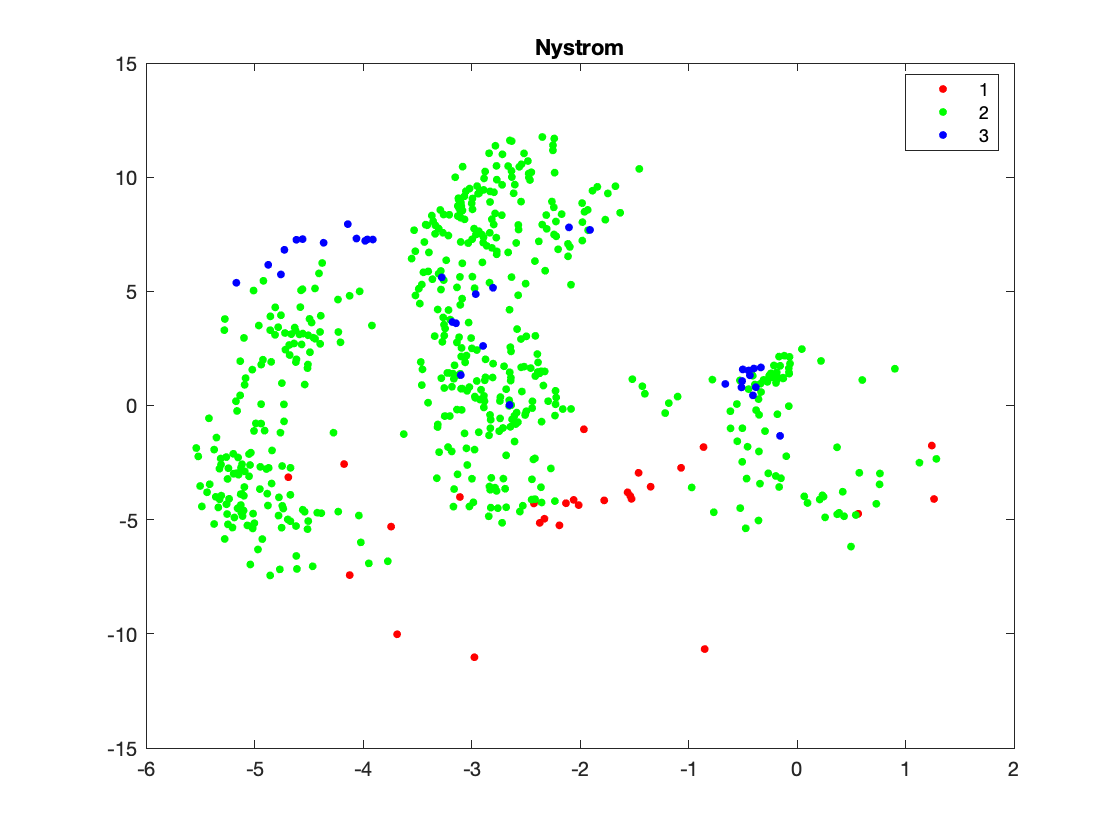

[U2, e2] = snapshot_pca(M.', 4, size(M,1)); % execute with transpose in order to get a matrix of n x m
[U3, e3, t] = pca_gram(M, center(M), 4, true);
D1 = (M - mean(M,2)) * U1;
D2 = (M - mean(M,2)) * U2;
D3 = (M - mean(M,2)) * U3;
figure
gscatter(D1(:,1),D1(:,2), Y)
title("Nystrom")
set(gcf, "Visible", "on")
saveas(gcf, "img/scatter_full_nystrom.pdf")

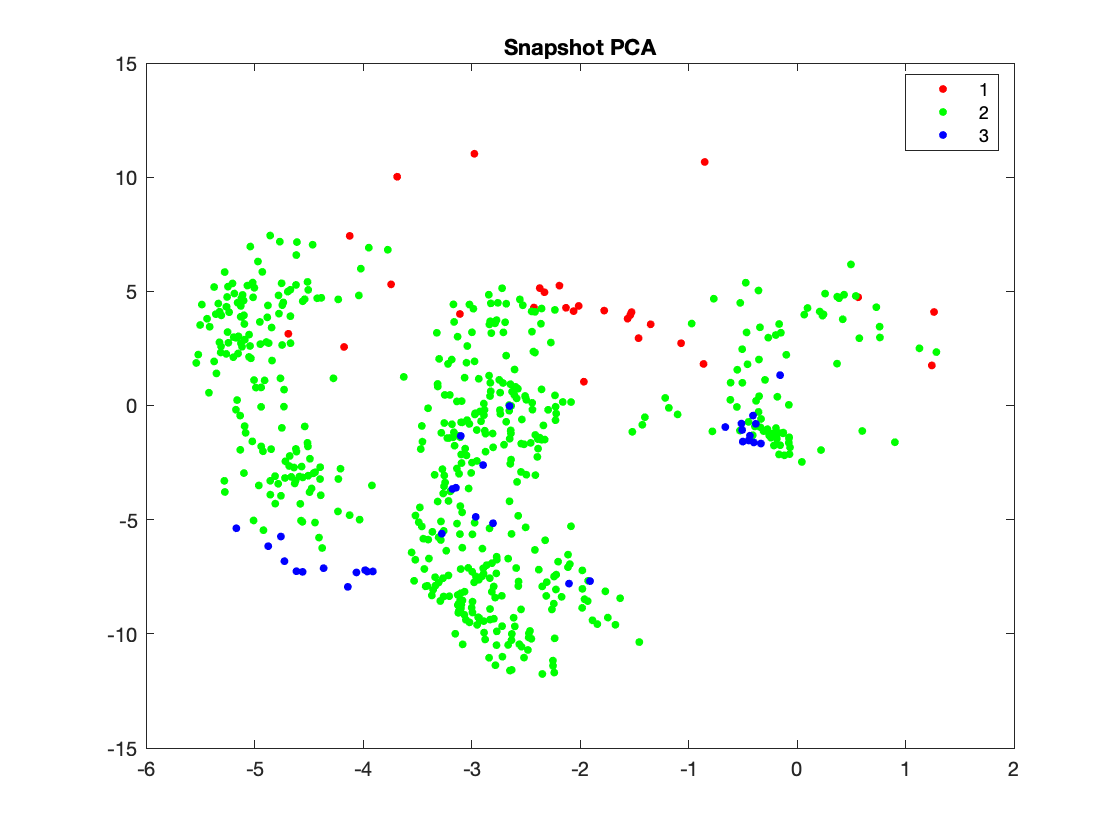

figure
gscatter(D2(:,1),D2(:,2), Y)
title("Snapshot PCA")
set(gcf, "Visible", "on")
saveas(gcf, "img/scatter_full_snapshot_pca.pdf")

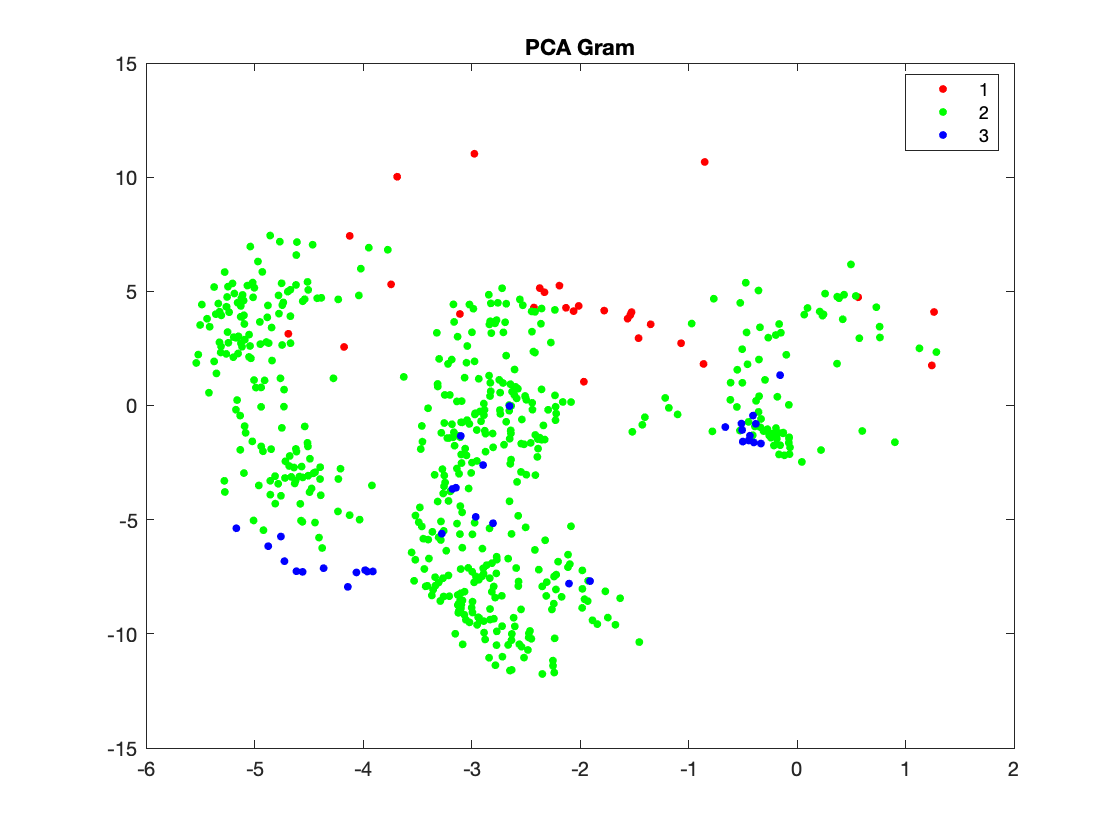

figure
gscatter(D3(:,1),D3(:,2), Y)
title("PCA Gram")
set(gcf, "Visible", "on")
saveas(gcf, "img/scatter_full_pca_gram.pdf")

Runtime/RE experiment for varying lambda values:

%% Graphs plotting experiment of Time/RE tradeoff for L
L1 = [605, 500, 400, 300, 200, 100, 50, 25, 10];
L2 = [6399, 5000, 4000, 3000, 2000, 1000, 500, 250, 100, 50];

[T1,E1,T2,E2] = experiment_data(L1, L2);
figure
yyaxis left
errorbar(L1,mean(T1,2),std(T1,0,2))
title("Execution Time and RE over varying values of L running Snapshot PCA")
hold on
yyaxis right
errorbar(L1,mean(E1,2),std(E1,0,2))
legend('Time in seconds', 'Reconstruction Error', 'Location','northwest')
hold off
figure
yyaxis left
errorbar(L2,mean(T2,2),std(T2,0,2))
title("Execution Time and RE over varying values of L running Nystrom")
hold on
yyaxis right
errorbar(L2,mean(E2,2),std(E2,0,2))
legend('Time in seconds', 'Reconstruction Error', 'Location','northwest')
hold off


Plot first 3 eigenfaces of drivface using varying lambda values:

% Lambda values for snapshot 1:606
L1 = [500,250,50];
% Lambda values for nystrom 1:6400
L2 = [5000, 2500, 500];

Eigen1 = zeros(3,3,80,80);
% Store eigenfaces of snapshot
for j = 1:3
    l = L1(j)
    [U, e] = snapshot_pca(M.',3, l);
    for i = 1:3
        Eigen1(j,i,:,:) = reshape(U(:,i)*100,80,80);
    end
end

% Store eigenfaces of nystrom
Eigen2 = zeros(3,3,80,80);
for j = 1:3
    l = L2(j)
    [U, e] = nystrom_method(M.',3, l);
    for i = 1:3
        Eigen2(j,i,:,:) = reshape(U(:,i)*100,80,80);
    end
end

% Plot eigenfaces
figure
tiledlayout(3,3);
for i = 1:3
    for j = 1:3
        nexttile;
        imshow(reshape(Eigen1(i,j,:,:),80,80))     % a  bit redundant....
        xlabel(sprintf('Eigen Face %i', j))
        if j == 1
            ylabel(sprintf('L = %i', L1(i)))
        end
    end
end
set(gcf, 'Visible', 'on')
saveas(gcf, "img/eigenfaces_snapshot_pca.pdf")

figure
tiledlayout(3,3);
for i = 1:3
    for j = 1:3
        nexttile;
        imshow(reshape(Eigen2(i,j,:,:),80,80))     % a  bit redundant....
        xlabel(sprintf('Eigen Face %i', j))
        if j == 1
            ylabel(sprintf('L = %i', L2(i)))
        end
    end
end
set(gcf, 'Visible', 'on')
saveas(gcf, "img/eigenfaces_nystrom.pdf")

Finally, we plot the the reconstructed faces for varying levels of D and L

% Lambda values for snapshot 1:606
L1 = [500,250,100];
% Lambda values for nystrom 1:6400
L2 = [5000, 2500, 500];

D = [2, 50 ,100];

m = M(10,:)

figure
tiledlayout(3,3)
for i = 1:3
    l = L1(i)
    for j = 1:3        
        d = D(j)
        nexttile
        [U, e] = snapshot_pca(M.',d, l);
        m_r = m * (U * U.');
        imshow(reshape(m_r, 80, 80))
        xlabel(sprintf("D = %i (e = %.2f)", d, e))
        if j == 1
            ylabel(sprintf("L = %i", l))
        end
    end
end
set(gcf, 'Visible', 'on')
saveas(gcf, "img/reconstructed_faces_snapshot_pca.pdf")

figure
tiledlayout(3,3)
for i = 1:3
    l = L2(i)
    for j = 1:3        
        d = D(j)
        nexttile
        [U, e] = nystrom_method(M.',d, l);
        m_r = m * (U * U.');
        imshow(reshape(m_r, 80, 80))
        xlabel(sprintf("D = %i (e = %.2f)", d, e))
        if j == 1
            ylabel(sprintf("L = %i", l))
        end
    end
end
set(gcf, 'Visible', 'on')
saveas(gcf, "img/reconstructed_faces_nystrom.pdf")

## Define Functions

First we define the Snapshot PCA method:

function [U, e] = snapshot_pca(M, d, l)
    [n, m] = size(M);
    
    %% Snapshot PCA
    
    % Compute center and centered points
    center = mean(M, 2);
    Y = M - center;  
    
    % Randomly sample l of the m datapoints
    S = sort(randsample(m,l));

    % Compute Gram matrix of sampled datapoints
    subY = Y(:,S);
    G = subY.' * subY;  
    
    % Compute eigenvectors/eigenvalues of Gram matrix (divided by l < m)
    [V, L] = eig(G/l); 
    L = diag(L);  % map diagonal eigenvalues to vector
    % Get max d eigenvalues with their eigenvectors
    [K, I] = maxk(L, d);  % I stores the indices of top eigenvalues
    
    % Compute the basis vectors of the affine subspace
    U = zeros(n, d);
    for i = 1:d
        % Map eigenvectors from R^m to R^n
        U(:,i) = 1/sqrt(L(I(i))) * subY * V(:,I(i)); % calculate basis vectors b
        U(:,i) = U(:,i) / norm(U(:,i)); % normalize
    end
    
    %% Reconstruction error
    % Map centered data onto affine subspace and map back
    A = Y.' * (U * U.');
    % Square all errors
    E = (Y - A.').^2;
    % Compute error 
    e = sqrt(sum(E, 'all'));
end

Now for the Nyström method:

function [U, e] = nystrom_method(M, d, l)
    %% Nystrom Method
    [n,m] = size(M);
    % Sample l landmark coordinates into S
    S = randsample(n,l);
    notS = setdiff(1:n, S).';
    % Create permutation matrix P based on S
    p = cat(1,S,notS);
    I = eye(n);
    P = I(p,:);  
    % Pinv is the inverse permutation matrix
    Pinv = P.';  
    % Compute center en calculate centered points
    center = mean(M,2);
    Y = M - center;
    % Permute centered points
    permY = P*Y;  % pre-multiplying to permute the rows
    subY = Y(S,:);  % create l x m matrix 
    % Calculate convariance matrix of n x l
    Cov = (1/m) * permY * subY.'; 
    
    % Separate covariance matrix
    A = Cov(1:l,:);
    B = Cov(l+1:size(Cov,1),:);
    
    % Decompose A into eigenvectors and eigenvalues
    [Ua,La] = eig(A);
    
    % Select top l eigen values and eigen vectors
    [K, I] = maxk(diag(La), l);  % I stores the indices of top eigenvalues
    
    % Reorder eigenvalues and eigenvectors
    La = diag(K);
    Ua = Ua(:,I);
    
    % Create final PCA modes
    Utilde = [Ua; B*Ua*inv(La)]; 
    % Restore original order using inverse permutation matrix
    U = Pinv * Utilde;
    % First d columns of U are the PCA modes
    U = U(:, 1:d);  
    
    %% Reconstruction error
    % Map centered data onto affine subspace and map back
    A = Y.' * (U * U.');
    % Square all errors
    E = (Y - A.').^2;
    % Compute error 
    e = sqrt(sum(E, 'all'));
end

function [T1, E1, T2, E2] = experiment_data(L1,L2)
    DrivFace = load("data/DrivFace/DrivFace.mat"); % http://archive.ics.uci.edu/ml/datasets/DrivFace
    DFdata = DrivFace.drivFaceD.data;
    d = 2;
    
    T1 = [];
    E1 = [];
    for i = 1:size(L1,2)
        l = L1(i);
        for j = 1:50
            tic 
            [U, E1(i,j)] = snapshot_pca(DFdata.', d, l);
            T1(i,j) = toc;
        end 
    end 
    "Executed Snapshot PCA"
    
    T2 = [];
    E2 = [];
    for i = 1:size(L2,2)
        l = L2(i);
        for j = 1:5
            tic 
            [U, E2(i,j)] = nystrom_method(DFdata.', d, l);
            T2(i,j) = toc;
        end 
    end 
    "Executed Nystrom Method"
    
end


Code stolen from Thomas:

function [basis_vecs, e, t] = pca_gram(m, mc, d, compute_error)
    tic;
    [V, D] = eig(1/(size(mc, 1))*(mc*mc.'));        % Calculate eigenvalues of (1/m)YY^T (we have row data)
    [D_sorted, ind] = sort(diag(D), 'descend');     % Fetch the top d eigenvalues and indices
    eigen_vecs = V(:,ind(1:d));                     % Select the d best eigenvectors
    basis_vecs = zeros(size(mc, 2), d);             % Pre-allocate
    for i = 1:d
        eigenvalue = D_sorted(i);
        eigenvector = eigen_vecs(:,i);
        normed = (eigenvector/norm(eigenvector));
        basis_vec = 1/sqrt(eigenvalue) * mc.' * normed; % Calculate basis vector i
        basis_vecs(:,i) = basis_vec / norm(basis_vec);
    end
    t = toc;
    if compute_error
        e = reconstruction_error(m, basis_vecs); % For some reason the error increases with Gram PCA. No idea what is going on.
    end
end

function e = reconstruction_error(m, basis_vecs)
    mc = center(m);
    MC_res = mc * (basis_vecs * basis_vecs.');
    error_mat = norm(mc - MC_res, 'fro');
    e = sum(error_mat);
end

function mc = center(m)
    m_mean = mean(m, 1);                            
    mc = m;
    for i=1:size(m,1)
        mc(i,:) = mc(i,:) - m_mean;
    end
end